clc; clear; close all;
T=imageDatastore("X-Ray with Tuberculosis");
NT=datastore('X-Ray normal');

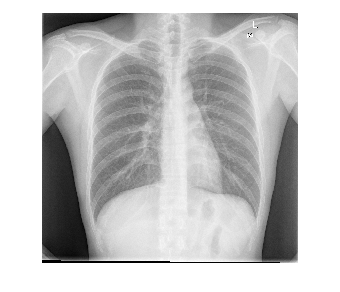

I=readimage(NT,25);
I=im2gray(I); %converting the image to gray scale
invI=255-I;
imshow(invI)

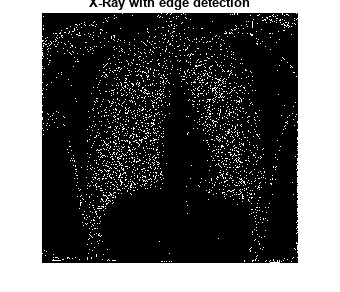

[~,thresh]=edge(I,'canny'); %decting the edge threshhold
fudgeFactor=0.9;  %
Iedge=edge(invI,'canny',thresh*fudgeFactor);%image with edge detection
figure(2)
imshow(Iedge)
title('X-Ray with edge detection')

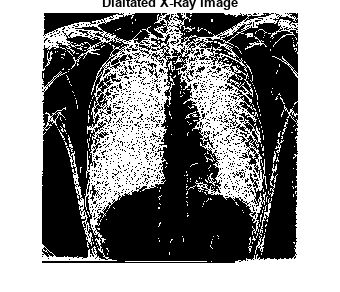

se90=strel("line", 3,90); %linear structural elements
se0=strel('disk',3,0); %linear structrual elements
Idilate=imdilate(Iedge,[se90 se0]); %dialted image
figure(3)
imshow(Idilate)
title('Dialtated X-Ray Image')

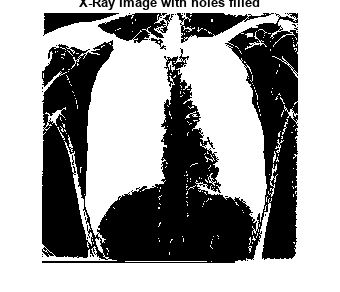

Ifill=imfill(Idilate,"holes"); %filling holes in the images
figure(4)
imshow(Ifill)
title('X-Ray Image with holes filled')

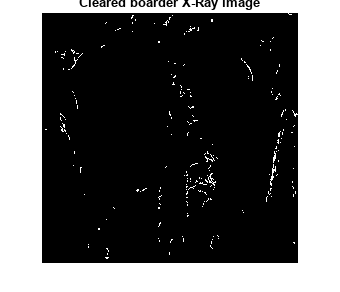

Iclear=imclearborder(Ifill,4); %clearing the border around distuinct parts of the binary image
figure(5)
imshow(Iclear)
title('Cleared boarder X-Ray image')

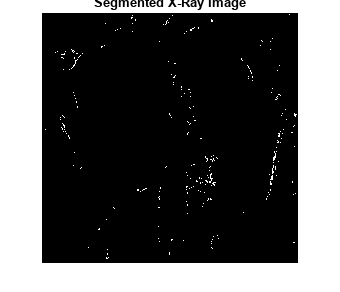

seD=strel('diamond',1); %creating a structural variable to fill area around each pixel defined
Ifinal=imerode(Iclear,seD); %using the variable created to smooth the iamge
Ifinal=imerode(Ifinal,seD); %smoothing the image again to get a better output
figure(6)
imshow(Ifinal)
title('Segmented X-Ray Image')

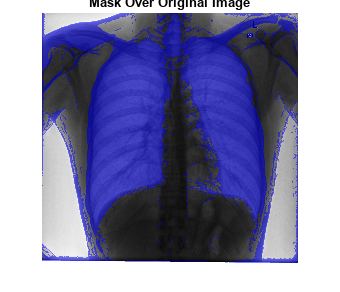

figure(7)
imshow(labeloverlay(I,Ifill)) %overlaying the final image on original image
title('Mask Over Original Image')